%%%%%%%%%%%%%%%%%%%%%%
%%% evaluating goodness of WRF data for actual met conditions
%%% created: 12-15-2022
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%% import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/Met %change to data folder

% airport observations
obs = struct();
obs.MGE = readtable("Met_STER.xlsx"); %MGE
obs.FTY = readtable("Met_SSG.xlsx"); %FTY
obs.CVC = readtable("Met_COV.xlsx"); %CVC

% wrf forecasts
wrf = struct();
wrf.MGE = readtable("WRF wind data.xlsx", "Sheet", "MGE"); %MGE
wrf.FTY = readtable("WRF wind data.xlsx", "Sheet", "FTY"); %FTY
wrf.CVC = readtable("WRF wind data.xlsx", "Sheet", "CVC"); %CVC
wrf.STER = readtable("WRF wind data.xlsx", "Sheet", "STER"); %STER
wrf.SSG = readtable("WRF wind data.xlsx", "Sheet", "SSG"); %SSG
wrf.COV = readtable("WRF wind data.xlsx", "Sheet", "COV"); %COV

cd ../../

%%%%%%%%%%%%%%%%%%%%%%
%%% limit obs to time period of wrf
%%%%%%%%%%%%%%%%%%%%%%

fields = fieldnames(obs); %field names (MGE, FTY, and CVC)
timeStart = wrf.MGE.time(1); %first time
timeEnd = wrf.MGE.time(end); %last time
for i = 1:length(fields)
    % grab inds of times between wrf period
    inds = isbetween(obs.(fields{i}).time, timeStart, timeEnd);
    obs.(fields{i})(~inds, :) = []; % remove other columns
end

%%%%%%%%%%%%%%%%%%%%%%
%%% retrieve paired wdr for all obs
%%%%%%%%%%%%%%%%%%%%%%

fields = fieldnames(obs); %field names (MGE, FTY, and CVC)
allWind = struct(); %pre-allocate WDR struct

for i = 1:length(fields) %loop through all airports
    tempTable = table(); %initiate table
    
    %% retrieve time, wdr, and wsp of obs
    tempTable.time = obs.(fields{i}).time; 
    tempTable.WDRobs = obs.(fields{i}).WDR;
    tempTable.WSPobs = obs.(fields{i}).WSP;
    % remove nan rows
    tempTable(isnan(tempTable.WDRobs), :) = [];

    %% assign relevant wrf wdr to obs wdr
    tempTime = dateshift(tempTable.time, ...
        "start", "hour"); % wdr assigned to hour prior to description
    % return vector of corresponding wrf wdr times to each obs
    [~, inds] = ismember(tempTime, wrf.(fields{i}).time);
    % remove obs rows that don't have matching wrf (5 days)
    tempTable(inds==0, :) = [];
    inds(inds==0) = []; %also remove indexing inds
    % retrieve wrf wdr and wsp values for table
    tempTable.WDRwrf = wrf.(fields{i}).WDR(inds);
    tempTable.WSPwrf = wrf.(fields{i}).WSP(inds);

    %% assign to struct
    allWind.(fields{i}) = tempTable;
end

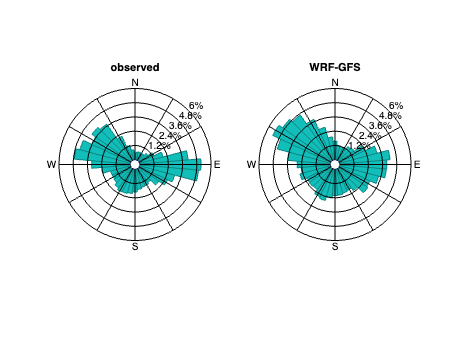

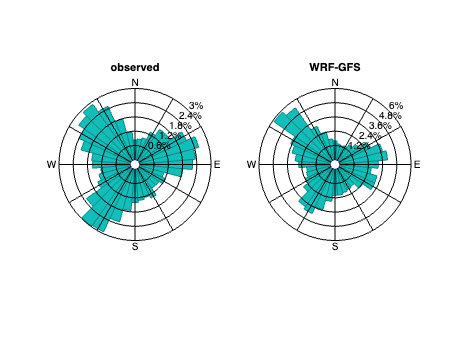

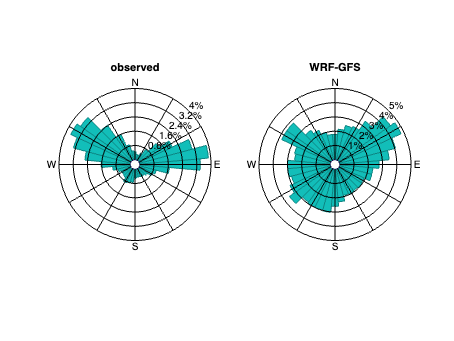

%%%%%%%%%%%%%%%%%%%%%%
%%% wind direction roses for ASOS to WRF-GFS comparisons
%%%%%%%%%%%%%%%%%%%%%%

cd ../Figures/'WRF WDR evaluation'/ %change to figure export folder

%% do wind roses for all data
for i = 1:length(fields) %plot wind roses for all sites
    % inputs
    tempObs = obs.(fields{i});
    tempWrf = wrf.(fields{i});

    fig = figure;
    % 1. obs windrose
    ax(1) = subplot(1,2,1);
    WindRose(tempObs.WDR, ones(size(tempObs.WDR)), 'anglenorth', 0, ...
        'angleeast', 90, 'legendtype', 0, 'titlestring', 'observed', ...
        'freqlabelangle', 45, 'axes', ax(1));
    % 2. wrf windrose
    ax(2) = subplot(1,2,2);
    WindRose(tempWrf.WDR, ones(size(tempWrf.WDR)), 'anglenorth', 0, ...
        'angleeast', 90, 'legendtype', 0, 'titlestring', 'WRF-GFS', ...
        'freqlabelangle', 45, 'axes', ax(2));
    %%export the figure
    fn = strcat(fields{i}, " all.png");
    exportgraphics(fig, fn)
end

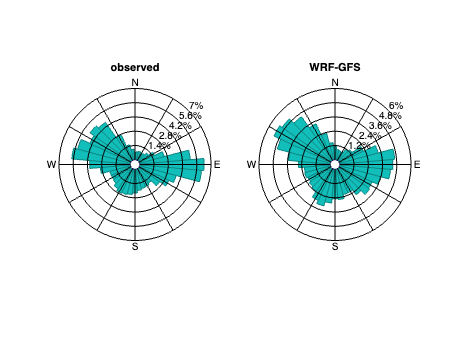

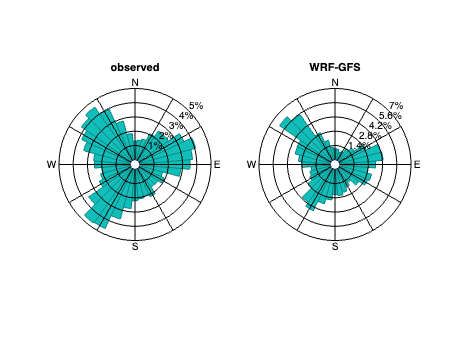

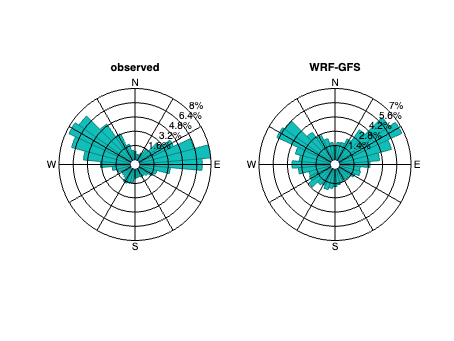


%% do wind roses for only matching data
for i = 1:length(fields) %plot wind roses for all sites

    fig = figure;
    % 1. obs windrose
    ax(1) = subplot(1,2,1);
    WindRose(allWind.(fields{i}).WDRobs, ones(size(allWind.(fields{i}).WDRobs)), ...
        'anglenorth', 0, 'angleeast', 90, 'legendtype', 0, ...
        'titlestring', 'observed', 'freqlabelangle', 45, 'axes', ax(1));
    % 2. wrf windrose
    ax(2) = subplot(1,2,2);
    WindRose(allWind.(fields{i}).WDRwrf, ones(size(allWind.(fields{i}).WDRwrf)), ...
        'anglenorth', 0, 'angleeast', 90, 'legendtype', 0, ...
        'titlestring', 'WRF-GFS', 'freqlabelangle', 45, 'axes', ax(2));

    %%export the figure
    fn = strcat(fields{i}, " matching.png");
    exportgraphics(fig, fn)
end


cd ../../Data %return to data folder

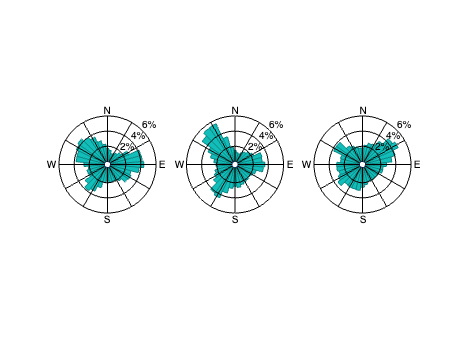

%%%%%%%%%%%%%%%%%%%%%%
%%% wind direction roses for WRF at STER, SSG, and COV
%%%%%%%%%%%%%%%%%%%%%%

cd ../Figures/'WRF WDR evaluation'/ %change to figure export folder
sites = ["STER", "SSG", "COV"]; %near-source sites

%plot wind roses for all sites
fig = figure;
for i = 1:length(sites)
    ax(i) = subplot(1, 3, i);
    WindRose(wrf.(sites(i)).WDR, ones(size(wrf.(sites(i)).WDR)), ...
        'anglenorth', 0, 'angleeast', 90, 'legendtype', 0, 'nfreq', 3, ...
        'titlestring', '', 'freqlabelangle', 45, 'maxfrequency', 6, ...
        'axes', ax(i));
end

%%export the figure
fn = "near-source WRF.png";
exportgraphics(fig, fn)


cd ../../Data

%%%%%%%%%%%%%%%%%%%%%%
%%% do correlations on data
%%%%%%%%%%%%%%%%%%%%%%

%%% use circ_corrcc to evaluate rho and p-val for each
correlStats = table(); % for all correlation stats
correlStats.site = fields;

for i = 1:length(fields) %loop through all airports
    correlStats.n(i) = length(allWind.(fields{i}).WDRobs); %number comparisons
    
    % do circular correlation
    [correlStats.rho(i), correlStats.pval(i)] = circ_corrcc( ...
        circ_ang2rad(allWind.(fields{i}).WDRobs), ...
        circ_ang2rad(allWind.(fields{i}).WDRwrf));
    
    % linear correlation just to compare
    correlStats.r(i) = corr(allWind.(fields{i}).WDRobs, ...
        allWind.(fields{i}).WDRwrf);
end

%%%%%%%%%%%%%%%%%%%%%%
%%% write to table
%%%%%%%%%%%%%%%%%%%%%%

cd ./Analysis/
writetable(correlStats, "WRF WDR evaluation.xlsx")
cd ..